%spike generation
X = zeros(200,1280);
%X(2,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x;
%X(1,:) = (1+a*(u(t-t1)-u(t-t2))).*x;

i = 1;
%for i = 1:200
    for k = 0.1:0.1:0.4     % alpha parameter
        for d = 0.0002:0.0001:0.001     %duration of disturbance
            for t2 = 0.003:0.001:0.01   %ending time stamp of disturbance
                t = 0:0.0003125:0.4-0.0003125;
                A = 1;
                %a = 0.2;
                f = 50;
                w = 2*pi*f;
                x = A*sin(w.*t);
                u = inline('t>=0');
                t1 = t2 - d;
                p=0;
                for i=0:1:9
                     p = p + k*(u(t-(t1-0.02*i))-u(t-(t2-0.02*i)));
                end

                X(i,:) = (sin(w.*t)+sign(sin(w.*t))).*p;
                                      
                i = i+1;
            end
        end
    end
%end

X

X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

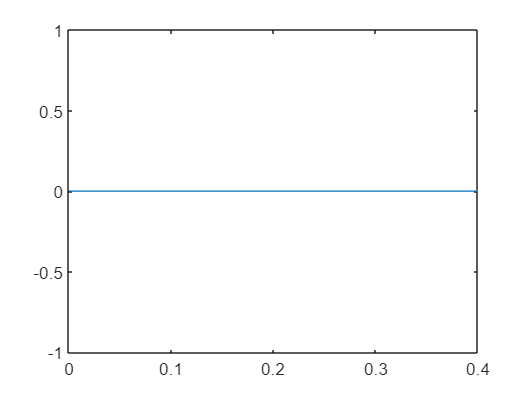

            
plot(t,X(121,:)) 

plot(t,X(1,:))

plot(t,X(30,:))

%X(167,:) = (1+a*(u(t-0.12)-u(t-0.22))).*x
%plot(t,x1)




